## **Import the package:**

import bh_rots_PKG.*

## A refresher on  DCM - via Euler angles

syms phi theta psi

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi],'SYM');

And look at what you have - here's the DCM

- $^Bv = {^BR_G}.^Gv$      where   $ {^BR_G} = 
R_{3X}(Roll) \enspace . \enspace 
R_{2Y}(Pitch)\enspace . \enspace R_{1Z}(Yaw)$   

tmp_R3R2R1 = OBJ_pass_rot.get_R3R2R1

$$tmp\_R3R2R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Here are the 3 individual PASSIVE rotation matrices:

tmp_R1 = OBJ_pass_rot.get_R1

$$tmp\_R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

tmp_R2 = OBJ_pass_rot.get_R2

$$tmp\_R2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

tmp_R3 = OBJ_pass_rot.get_R3

$$tmp\_R3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## An initial and Final pose

OBJ_pass_init = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'},  [0,     0,  0],'DEGREES');
OBJ_pass_final = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [135, -30, 50],'DEGREES'); 

Plot stuff

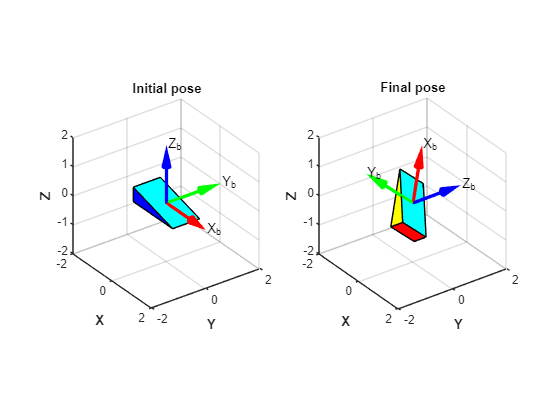

hfig =  figure;
hax(1) = subplot(1,2,1);
         LOC_plot_stuff(OBJ_pass_init.get_R3R2R1() , hfig, hax(1));
         title('Initial pose')
hax(2) = subplot(1,2,2);
         LOC_plot_stuff(OBJ_pass_final.get_R3R2R1(), hfig, hax(2));  
         title('Final pose')

#### Create quaternions for these INITIAL and FINAL poses

q_OBJ  = bh_quat_rot_CLS();

q_init  = q_OBJ.calc_q_from_dcm(OBJ_pass_init.get_R3R2R1()  );
q_init.'

ans =      1     0     0     0



q_final = q_OBJ.calc_q_from_dcm(OBJ_pass_final.get_R3R2R1() );
q_final.'

ans =     0.2340    0.3729    0.2874    0.8506


#### So let's interpolate from INITIAL to FINAL

Let's utilise the [`quatinterp()`](matlab:  web(fullfile(docroot, 'aerotbx/ug/quatinterp.html'))) function from the Aerospace toolbox, to interpolate from INITIAL to FINAL

NUM_POINTS = 50;
q_mat      = zeros(4, NUM_POINTS);
f_vec      = linspace(0,1, NUM_POINTS)';

for kk=1:NUM_POINTS
    % do the SLERP
    q_tmp = quatinterp(q_init' , q_final', f_vec(kk),'slerp');
    q_mat(:,kk) = q_tmp' ;
end

and visualize

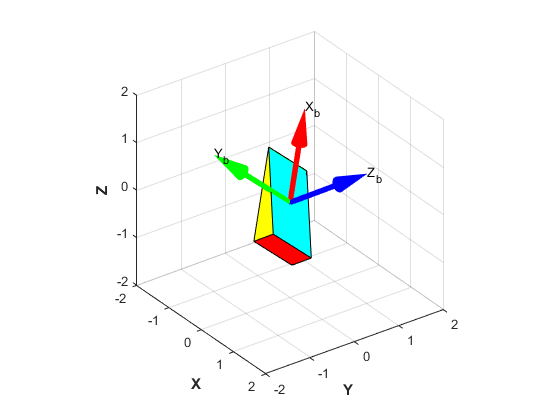

LOC_animate_the_SLERP(q_mat, q_OBJ)

# Local subfunctions only beyond this point

 function LOC_plot_stuff(DCM_bRg, hfig, hax)
  % ALLOWED USAGE:
  %   >> LOC_plot_stuff(DCM)
  %   >> LOC_plot_stuff(DCM, hfig, hax)  
  
    if(1==nargin)
        hfig = figure;
        hax  = axes();
    end
 
    import bh_rots_PKG.bh_vehicle_CLS
 
    DCM_gRb = DCM_bRg.';    
    
    veh_OBJ = bh_vehicle_CLS();              
    veh_OBJ = veh_OBJ.rotate_using_gRb(DCM_gRb);
    
    % plot stuff
    veh_OBJ.plot_3D(hax);
    
 end

A plot to animate the SLERP

function LOC_animate_the_SLERP(q_mat, q_OBJ)
     
     NUM_POINTS = size(q_mat, 2);
     
    for kk=1:NUM_POINTS    
        if(1==kk)
           hf = figure;
           hax = axes;
        end
        
        q = q_mat(:,kk);
       my_DCM = q_OBJ.calc_dcm_from_q(q);
       cla(hax)
       LOC_plot_stuff(my_DCM, hf, hax);
       drawnow
    end 
 
end